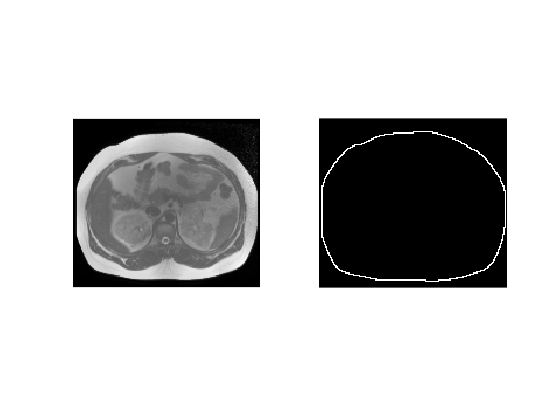

%Load the dataset and show the images with their segmentations
data1 = load("dataForNN_foreBorder_clip0.mat");
data2 = load("dataForNN_foreBorder_clip1.mat");
data3 = load("dataForNN_inside_clip0.mat");

figure();
subplot(1, 2, 1), imshow(data1.trainingImage);
subplot(1, 2, 2), imshow(data1.trainingSegmentation);

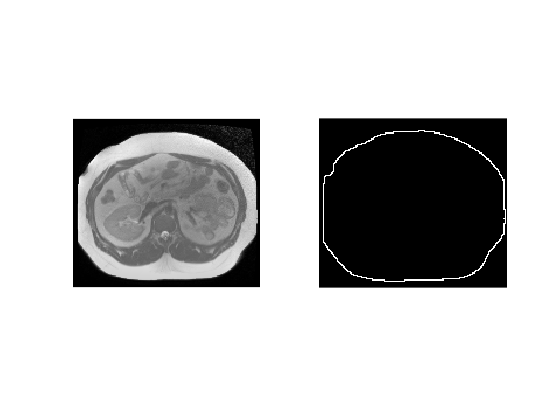


figure();
subplot(1, 2, 1), imshow(data1.testImage, []);
subplot(1, 2, 2), imshow(data1.testSegmentation, []);

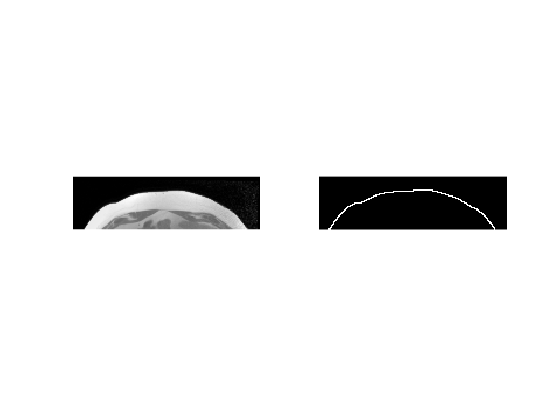



figure();
subplot(1, 2, 1), imshow(data2.trainingImage, []);
subplot(1, 2, 2), imshow(data2.trainingSegmentation, []);

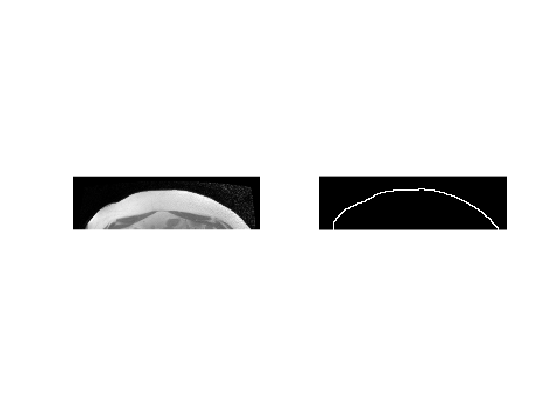


figure();
subplot(1, 2, 1), imshow(data2.testImage, []);
subplot(1, 2, 2), imshow(data2.testSegmentation, []);

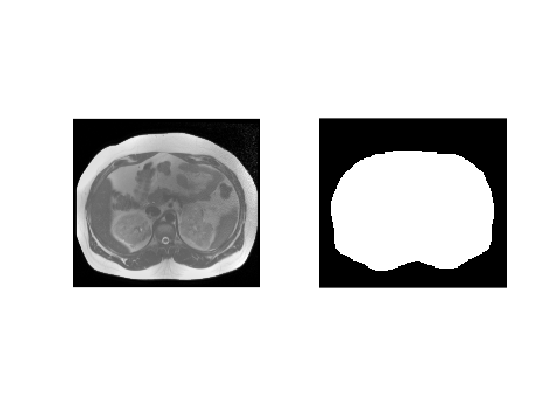


figure();
subplot(1, 2, 1), imshow(data3.trainingImage, []);
subplot(1, 2, 2), imshow(data3.trainingSegmentation, []);

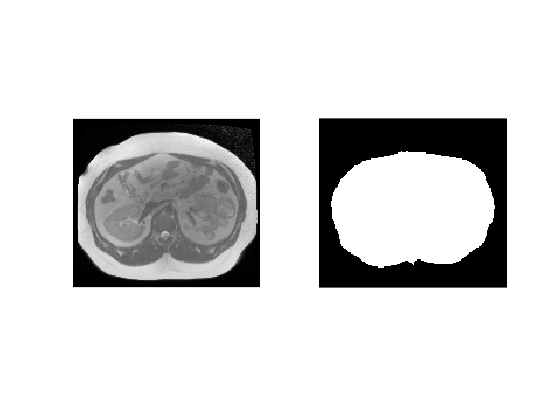


figure();
subplot(1, 2, 1), imshow(data3.testImage, []);
subplot(1, 2, 2), imshow(data3.testSegmentation, []);

%Define Beta vector, cost vector, stepsize and the training/testing image
maxIter = 5000;
M = 6;
Beta = zeros([1, 6]);
ImTrain = data3.trainingImage;
ImTrainSegm = data3.trainingSegmentation;
ImTest = data3.testImage;
ImTestSegm = data3.testSegmentation;
stepSize = 0.005;
costVectorTrain = zeros([1 maxIter]);
costVectorTest = zeros([1 maxIter]);


for k = 1:maxIter
    randPerm = randperm(length(ImTrain(:)), 200);
    ImTrainRes = zeros(size(ImTrain));
    ImTestRes = zeros(size(ImTest));
    for j = 1:M
        ImTrainRes = ImTrainRes + Beta(j) * BasisFun(ImTrain, j);
        ImTestRes = ImTestRes + Beta(j) * BasisFun(ImTest, j);
    end
    ImTrainRes = Sigmoid(ImTrainRes);
    ImTestRes = Sigmoid(ImTestRes);
    costVectorTrain(k) = getCost(ImTrainRes, ImTrainSegm, randPerm);
    costVectorTest(k) = getCost(ImTestRes, ImTestSegm, randPerm);
    delta = 0.001;
    Gradient = zeros(size(Beta));
    for i = 1:length(Beta)
        newBeta = Beta;
        newBeta(i) = newBeta(i) + delta;
        ImTrainRes = zeros(size(ImTrain));
        for j = 1:M
            ImTrainRes = ImTrainRes + newBeta(j) * BasisFun(ImTrain, j);
        end
        ImTrainRes = Sigmoid(ImTrainRes);
        newCost = getCost(ImTrainRes, ImTrainSegm, randPerm);
        Gradient(i) = (newCost - costVectorTrain(k)) / delta;
    end
    Beta = Beta - stepSize * Gradient;
end
ImTrainRes = zeros(size(ImTrain));
for i = 1:6
    ImTrainRes = ImTrainRes + Beta(i) * BasisFun(ImTrain, i);
end
ImTrainRes = Sigmoid(ImTrainRes);

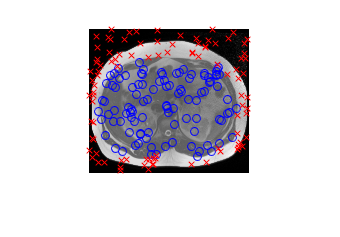

%Obtain indices of the 200 random points from the last iteration where the segmentation is 1/0
randPermTrue = randPerm(ImTrainSegm(randPerm) == 1);
randPermFalse = randPerm(ImTrainSegm(randPerm) == 0);
%Plot the points on the image
figure();
imshow(data3.trainingImage)
hold on;
plot(idivide(int16(randPermTrue), size(data3.trainingImage, 1)), ...
    mod(randPermTrue, size(data3.trainingImage, 1)), 'ob')
plot(idivide(int16(randPermFalse), size(data3.trainingImage, 1)), ...

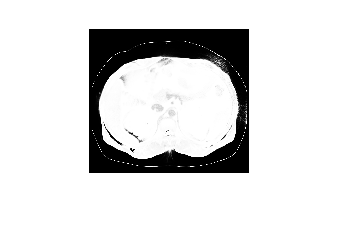

    mod(randPermFalse, size(data3.trainingImage, 1)), 'xr')
%Plot the posterior of the training image
figure();
imshow(ImTrainRes)

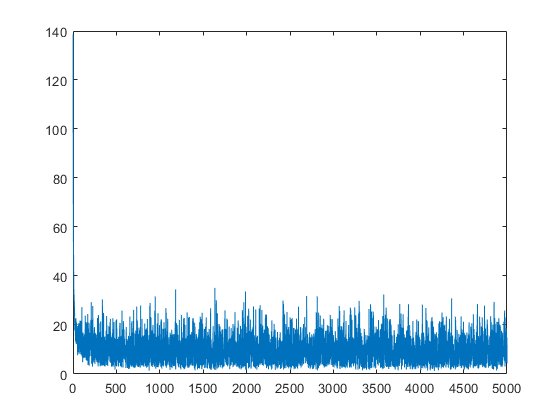

%Plot the progression of the cost vector throughout the iterations
figure();
plot(costVectorTrain);

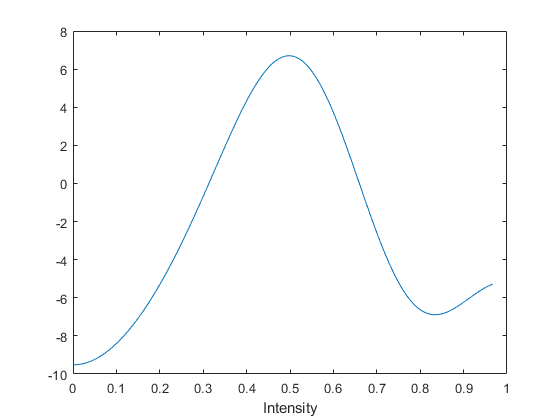

% hold on;
% plot(costVectorTest);
% hold off;
% legend("Training dataset", "Testing dataset")
%Plot the value of a = sum(beta * basisFunction) across the intensity
%values
X = 0:0.001:max(ImTrain(:));
Y = Beta(1) * BasisFun(X, 1);
for i = 2:6
    Y = Y + Beta(i) * BasisFun(X, i);
end
figure();
plot(X,Y)
xlabel("Intensity")

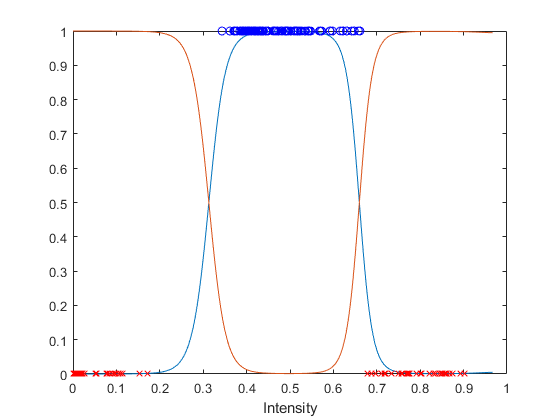

figure();
%Plot the squashed sigma(a) and add the selected points from the previous
%iteration
plot(X, Sigmoid(Y))
hold on;
plot(X, 1 - Sigmoid(Y))
plot(ImTrain(randPermTrue), 1, 'ob')
plot(ImTrain(randPermFalse), 0, 'xr')
xlabel("Intensity")
hold off;

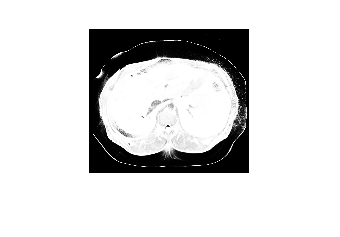

%Apply the model to the test image
ImTest = data3.testImage;
ImTestRes = zeros(size(ImTest));
for i = 1:6
    ImTestRes = ImTestRes + Beta(i) * BasisFun(ImTest, i);
end
ImTestRes = Sigmoid(ImTestRes);
imshow(ImTestRes)

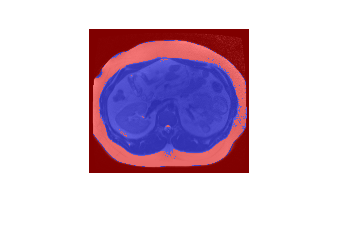

Blue = (ImTestRes > 0.5);
Red = (ImTestRes <= 0.5);
rgb = zeros(size(ImTest));
rgb(:, :, 1) = Red;
rgb(:, :, 3) = Blue;
imshowpair(ImTest, rgb, 'blend')

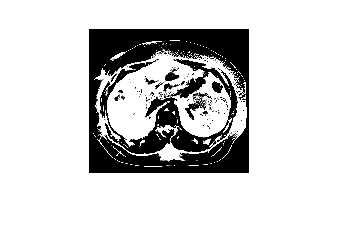

%Replace the test image with a new one with d=d^1.3 
ImTestNew = ImTest.^1.3;
figure();
subplot(1, 2, 1), imshow(ImTest), title("Original test image");
subplot(1, 2, 2), imshow(ImTestNew), title("Modified test image");
ImTestNewRes = zeros(size(ImTestNew));
for i = 1:6
    ImTestNewRes = ImTestNewRes + Beta(i) * BasisFun(ImTestNew, i);
end
figure();
imshow(ImTestNewRes)

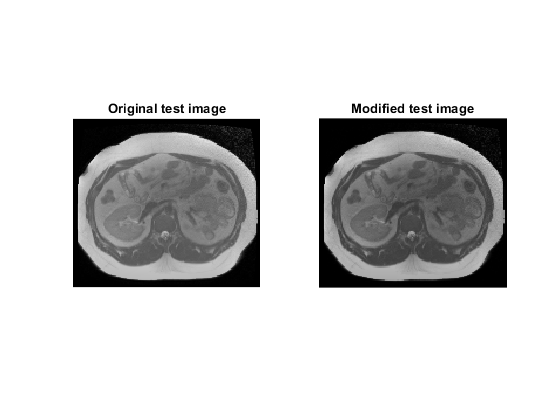

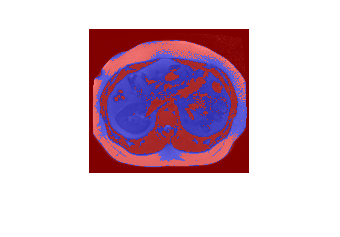

rgb(:, :, 1) = ImTestNewRes <= 0.5;
rgb(:, :, 3) = ImTestNewRes > 0.5;
figure();
imshowpair(ImTestNew, rgb, 'blend');

%Apply the convolutional neural network with p = 1
%Define the beta vector, weights
M = 6;
p = 1;
maxIter = 5000;
stepSize = 0.005;
Beta = zeros([1, M]);
ImTrain = data3.trainingImage;
ImTrainSegm = data3.trainingSegmentation;
ImTest = data3.testImage;
ImTestSegm = data3.testSegmentation;
costVectorTrain = zeros([1 maxIter]);
costVectorTest = zeros([1 maxIter]);
weights = normrnd(0, 1, M, p + 1);
for k = 1:maxIter
    %Take a random sample of points from the image
    randPerm = randperm(length(ImTrain(:)), 200);
    %Construct the segmentation
    ImTrainRes = zeros(size(ImTrain));
    ImTestRes = zeros(size(ImTest));
    for j = 1:M
        ImTrainRes = ImTrainRes + Beta(j) * AdBasisFun(ImTrain, weights, j, p);
        ImTestRes = ImTestRes + Beta(j) * AdBasisFun(ImTest, weights, j, p);
    end
    ImTrainRes = Sigmoid(ImTrainRes);
    ImTestRes = Sigmoid(ImTestRes);
    %Compute the cost given the computed segmentation
    costVectorTrain(k) = getCost(ImTrainRes, ImTrainSegm, randPerm);
    costVectorTest(k) = getCost(ImTestRes, ImTestSegm, randPerm);
    delta = 0.001;
    %Convert the beta and weights into a single vector
    Params = [Beta , reshape(weights.', 1, [])];
    Gradient = zeros(size(Params));
    for i = 1:length(Params)
        newParams = Params;
        newParams(i) = newParams(i) + delta;
        %Convert the parameter vector back into beta and weights
        newBeta = newParams(1:M);
        newWeights = reshape(newParams((M + 1):end), size(weights'))';
        %Construct the segmentation given one of the parameters slightly
        %adjusted
        ImTrainRes = zeros(size(ImTrain));
        for j = 1:M
            ImTrainRes = ImTrainRes + newBeta(j) * AdBasisFun(ImTrain, newWeights, j, p);
        end
        ImTrainRes = Sigmoid(ImTrainRes);
        newCost = getCost(ImTrainRes, ImTrainSegm, randPerm);
        Gradient(i) = (newCost - costVectorTrain(k)) / delta;
    end
    %Update the parameters
    Params = Params - stepSize * Gradient;
    Beta = Params(1:M);
    weights = reshape(Params((M + 1):end), size(weights'))';
end
disp("The parameters:")

The parameters:


Beta

Beta =     3.3591    3.1669    2.1784   -7.6100  -16.5157   -9.6797


weights

weights =     0.1000   -1.6529
    2.3455    2.5143
    2.1784    0.9002
    2.8568  -10.2660
   -9.5156   14.4376
    3.6322  -12.0655


%Section to test the function
M = 6;
p = 1;
maxIter = 5000;
stepSize = 0.005;
N = 200;
ImTrain = data3.trainingImage;
ImTrainSegm = data3.trainingSegmentation;
ImTest = data3.testImage;
ImTestSegm = data3.testSegmentation;
[Beta, weights, costVectorTrain, costVectorTest, randSamp] = ...
    StochGradDescentAdBasFun(ImTrain, ImTrainSegm, ImTest, ImTestSegm, ...
    M, p, stepSize, N, maxIter);
disp("The parameters with the defined function:")

The parameters with the defined function:


Beta

Beta =    -3.9235   13.8819  -15.3793   -3.9553    2.6745   -5.8165


weights

weights =    -0.0788   -0.4584
    8.7922  -13.4844
    4.6300  -14.7485
    0.0850    1.6500
   -1.3785    6.9499
   -2.8611    4.1524


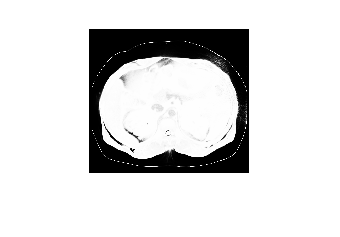

%Visualize the results and obtain the cost at the last iteration
ImTrainRes = zeros(size(ImTrain));
for i = 1:M
    ImTrainRes = ImTrainRes + Beta(i) * AdBasisFun(ImTrain, weights, i, p);
end
ImTrainRes = Sigmoid(ImTrainRes);
%Show the segmentation of the training image
figure();
imshow(ImTrainRes)

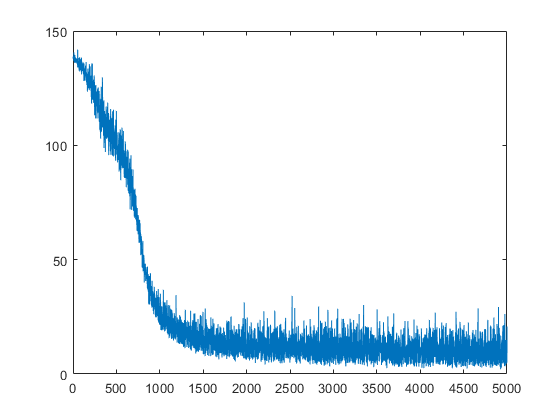

%Plot the evolution of the cost
figure();
plot(costVectorTrain)

%Show the cost at the last iteration
costVectorTrain(end)

ans = 20.7913

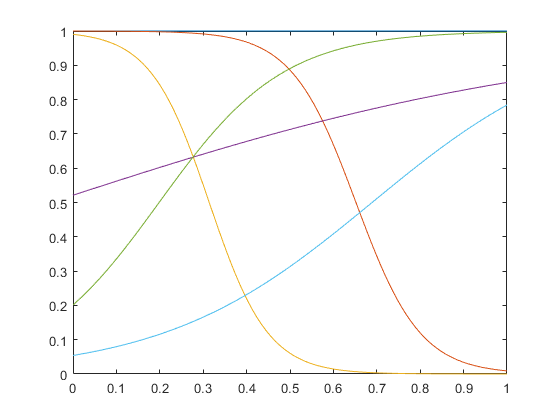

%Visualize the basis functions
figure();
X = linspace(0, 1, 100);


for i = 1:M
    plot(X, AdBasisFun(X, weights, i, 1));
    hold on;
end
hold off;

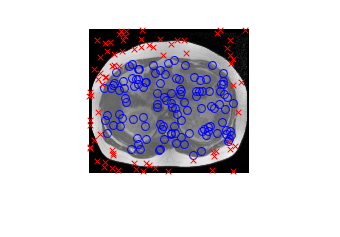

%Visualize the last iteration sample on the image
randPermTrue = randPerm(ImTrainSegm(randPerm) == 1);
randPermFalse = randPerm(ImTrainSegm(randPerm) == 0);
figure();
imshow(data3.trainingImage)
hold on;
plot(idivide(int16(randPermTrue), size(data3.trainingImage, 1)),...
    mod(randPermTrue, size(data3.trainingImage, 1)), 'ob')
plot(idivide(int16(randPermFalse), size(data3.trainingImage, 1)),...
    mod(randPermFalse, size(data3.trainingImage, 1)), 'xr')
hold off;

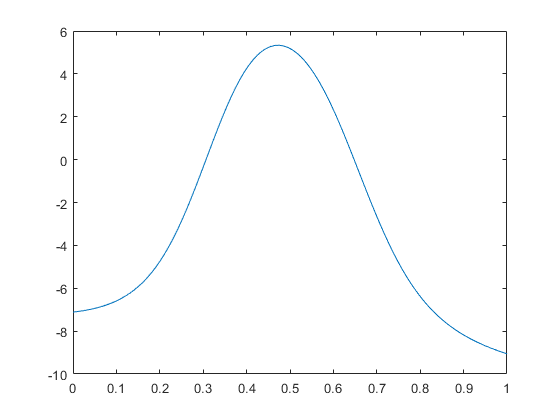

%Visualize the activation function
Y = zeros([1, length(X)]);
for i = 1:M
    Y = Y + Beta(i) * AdBasisFun(X, weights, i, 1);
end
figure();
plot(X, Y)

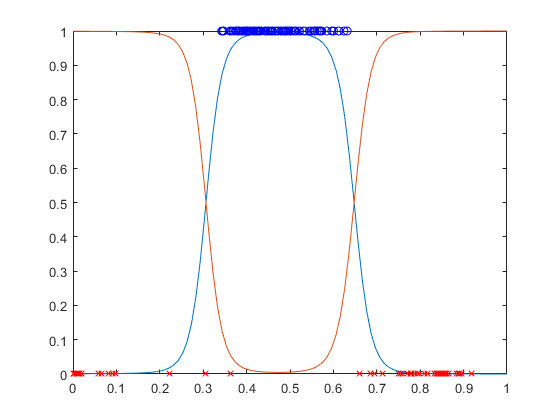

figure();
plot(X, Sigmoid(Y))
hold on;
plot(X, 1 - Sigmoid(Y));
plot(ImTrain(randPermTrue), 1, 'ob')
plot(ImTrain(randPermFalse), 0, 'xr')
hold off

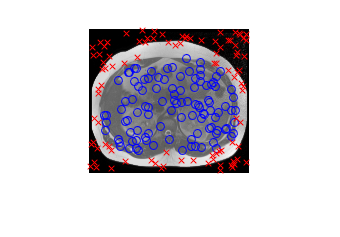

%Some testing section
weights

weights =    -1.2192   -0.5626
    2.2109  -12.0182
    2.8747   -0.9317
   -4.4579    6.7754
    0.5612   -1.6195
    2.0867    0.8700


weights(5) = weights(5) + delta

weights =    -1.2192   -0.5626
    2.2109  -12.0182
    2.8747   -0.9317
   -4.4579    6.7754
    0.5622   -1.6195
    2.0867    0.8700


a = [1 2; 3 4]

a =      1     2
     3     4


imfilter(a, [1 1])

ans =      3     2
     7     4


%Define the stochastic gradient descent function given the adaptive basis
%functions

function [Beta, weights, costVectorTrain, costVectorTest, randSamp] = ...
    StochGradDescentAdBasFun(ImTrain, ImTrainSegm, ImTest, ImTestSegm, M, p, stepSize, N, maxIter)
%This function executes a stochastic gradient optimizer and returns
%parameters Beta and weights, along with the evolution of the cost vector
%of the training/testing image and the indices of the sample points taken
%in the final iteration of the SGD
%PARAMETERS:
%ImTrain/ImTrainSegm : Training image/Segmentation
%ImTest/ImTestSegm : Testing image/Segmentation
%M : number of basis functions to be used
%p : type of adaptive basis function (p = 1 uses single point, p = 2 
%includes a point in the next row, p = 3 uses a 3x3 patch with the 
% point in the center)
%stepSize : stepSize for the SGD optimizer
%N : size of the random sample for SGD
%maxIter : maximum number of iterations
    Beta = zeros([1, M]);
    costVectorTrain = zeros([1 maxIter]);
    costVectorTest = zeros([1 maxIter]);
    weights = normrnd(0, 1, M, p + 1);
    for k = 1:maxIter
        %Take a random sample of points from the image
        randSamp = randperm(length(ImTrain(:)), N);
        %Construct the segmentation
        ImTrainRes = zeros(size(ImTrain));
        ImTestRes = zeros(size(ImTest));
        for j = 1:M
            ImTrainRes = ImTrainRes + Beta(j) * AdBasisFun(ImTrain, weights, j, p);
            ImTestRes = ImTestRes + Beta(j) * AdBasisFun(ImTest, weights, j, p);
        end
        ImTrainRes = Sigmoid(ImTrainRes);
        ImTestRes = Sigmoid(ImTestRes);
        %Compute the cost given the computed segmentation
        costVectorTrain(k) = getCost(ImTrainRes, ImTrainSegm, randSamp);
        costVectorTest(k) = getCost(ImTestRes, ImTestSegm, randSamp);
        delta = 0.001;
        %Convert the beta and weights into a single vector
        Params = [Beta , reshape(weights.', 1, [])];
        Gradient = zeros(size(Params));
        for i = 1:length(Params)
            newParams = Params;
            newParams(i) = newParams(i) + delta;
            %Convert the parameter vector back into beta and weights
            newBeta = newParams(1:M);
            newWeights = reshape(newParams((M + 1):end), size(weights'))';
            %Construct the segmentation given one of the parameters slightly
            %adjusted
            ImTrainRes = zeros(size(ImTrain));
            for j = 1:M
                ImTrainRes = ImTrainRes + newBeta(j) * AdBasisFun(ImTrain, newWeights, j, p);
            end
            ImTrainRes = Sigmoid(ImTrainRes);
            newCost = getCost(ImTrainRes, ImTrainSegm, randSamp);
            Gradient(i) = (newCost - costVectorTrain(k)) / delta;
        end
        %Update the parameters
        Params = Params - stepSize * Gradient;
        Beta = Params(1:M);
        weights = reshape(Params((M + 1):end), size(weights'))';
    end
end